clear
MSD_startup;
A = [0 1 0 0 0 0 ;
     -20 -0.2 20 0.02 0 0 ;
     0 0 0 1 0 0 ;
     20 0.2 -120 -0.12 40 0.4 ; 
     0 0 0 0 0 1 ;
     0 0 100 0.1 -44 -0.44];
B = [0 ; 0.2 ; 0 ; -0.2 ; 0 ; 0];
C = [1 0 1 0 0 0];
D = 0;
sys = ss(A,B,C,D);

QXU = blkdiag(C'*50*C, 0.001);
QWV = eye(7);
reg = lqg(sys, QXU, QWV);
Ksim = reg;

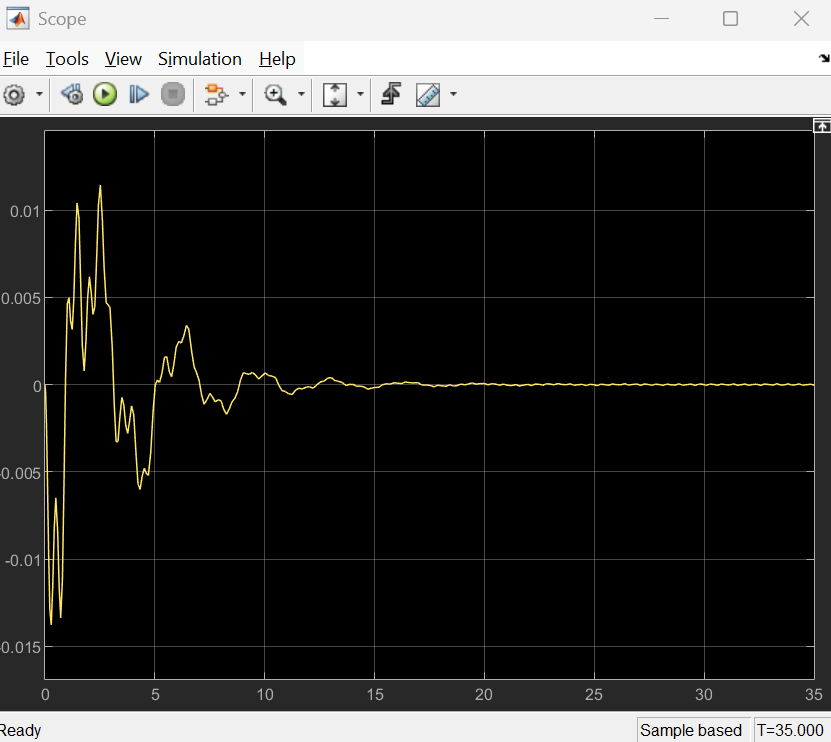

Response to a unit step disturbance.

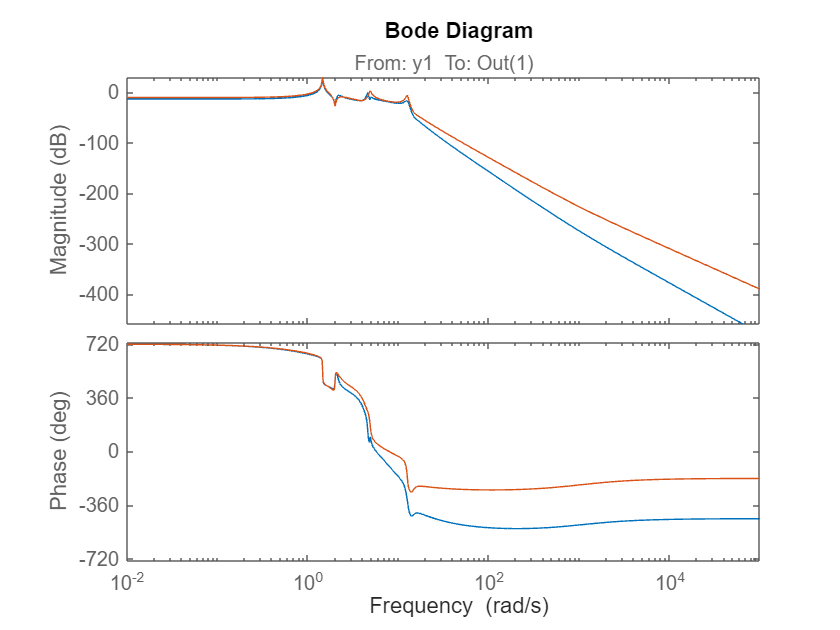

[Ksim, CL, GAM] = ncfsyn(sys, -reg, []);
bode(sys*Ksim, sys*reg)

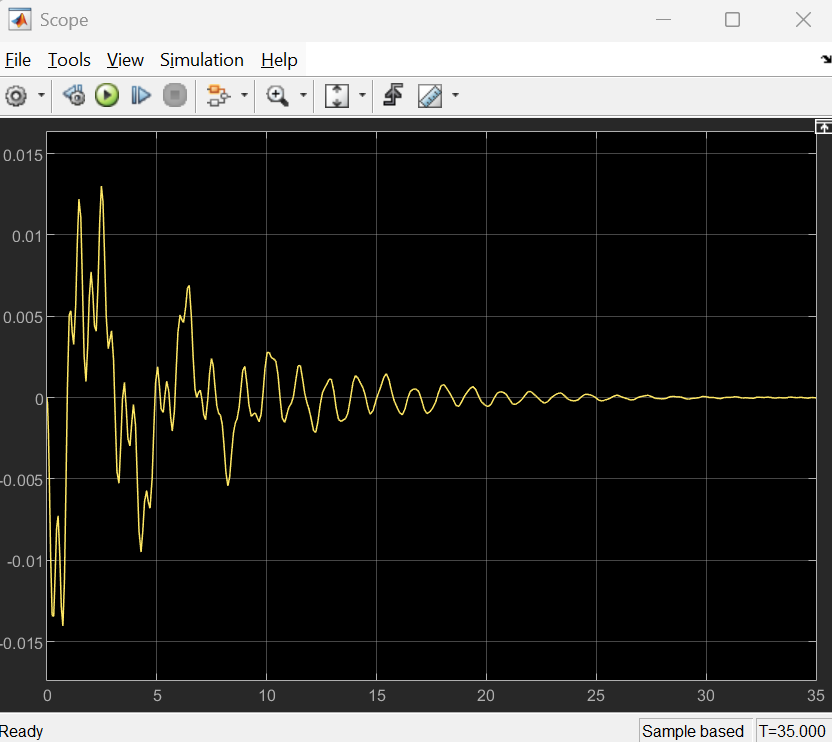

Response to a unit step disturbance.

MSD_startup;
m3 = ureal('m3', m3, 'Percentage', 3);

clear
s = tf('s');
alpha = [2 4 20 50 58];
for i=1:1:length(alpha)
    G = 0;
    for j=1:1:5
        G = G + alpha(i)^(2*j)/(s+alpha(i)^(2*j));
    end
    n = order(G);
    [sys, H] = balreal(G);
    H
end

H =     1.5721
    0.6413
    0.2087
    0.0611
    0.0167


H =     0.9917
    0.6885
    0.4185
    0.2453
    0.1560


H =     0.5894
    0.5485
    0.4967
    0.4490
    0.4165


H =     0.5351
    0.5198
    0.4995
    0.4798
    0.4658


Error using DynamicSystem/balreal (line 67)
Lyapunov equation is nearly singular.

As $\alpha$ approaches infinity, the Hankel singular values all converge. When they have converged, the Lyapunov equation becomes singular.

clear;
s = tf('s');
G0 = ((1-0.05*s)/(1+0.05*s))^10;
G1 = G0 * 1/(1+s*0.01);
G2 = G0 * 1/(1+s*0.1);
G3 = G0 * 1/(1+s*1);
G4 = G0 * 1/(1+s*10);

Using the Model Reduction Tool, I found that for T=0 and T=0.01, the error is only below 0.1 if no states are truncated. For T=0.1, the order can be reduced to 10 from 11. For T=1, the order can be reduced to 8, and for T=10, the order can be reduced to 3.

T=0

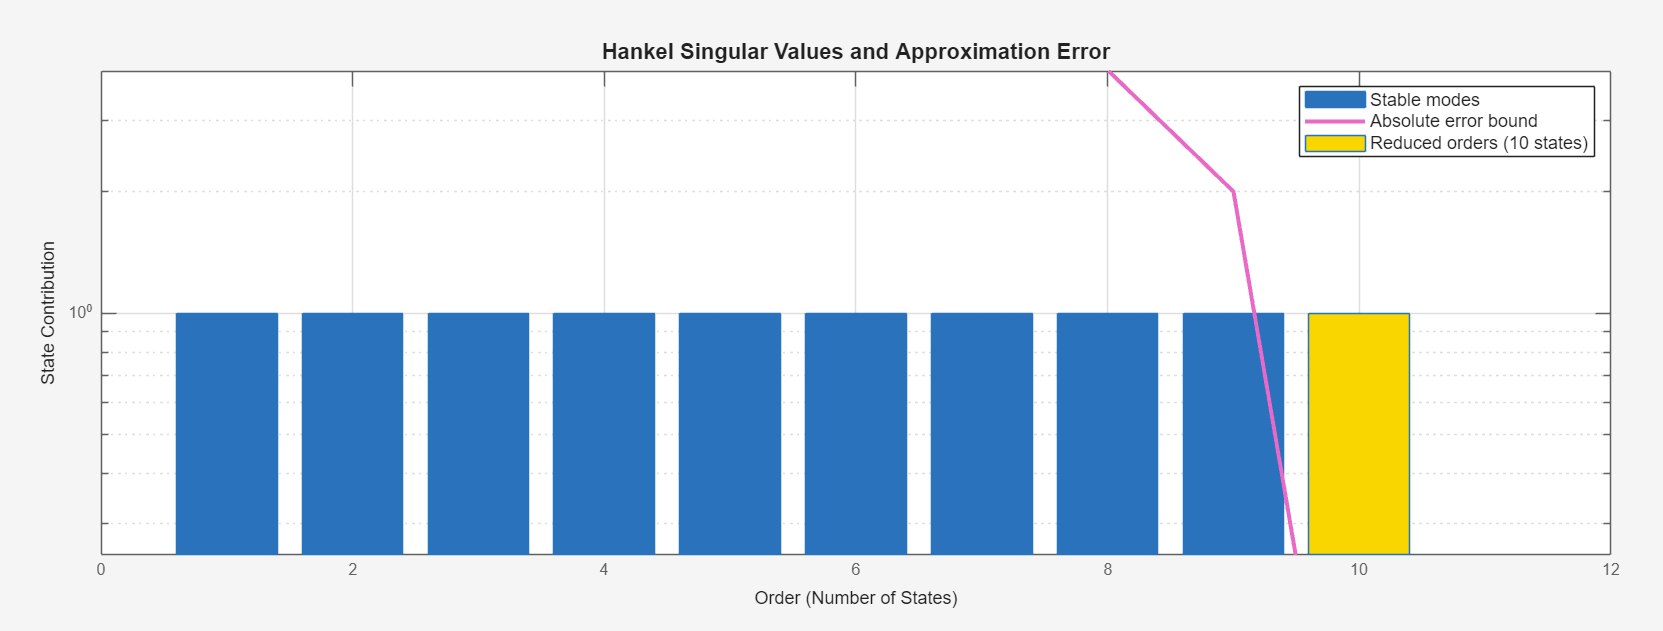

T=0.01

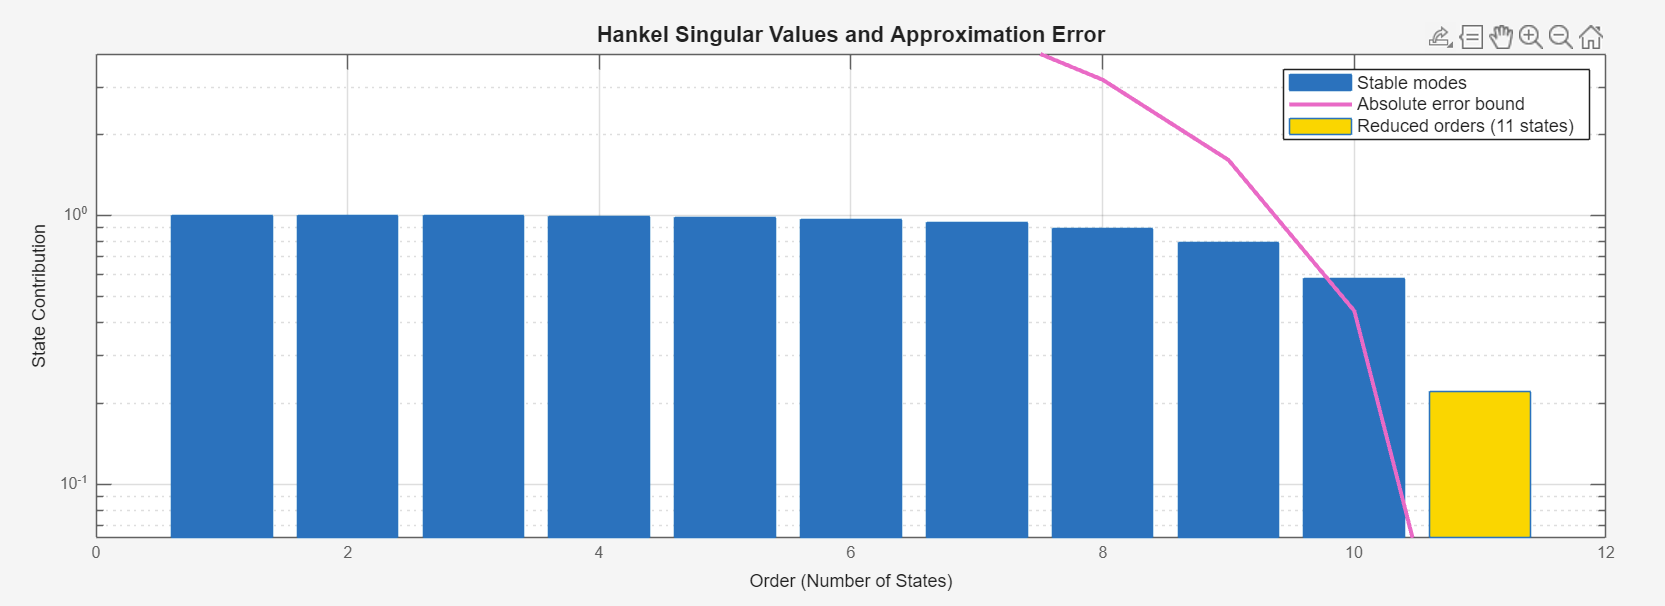

T=0.1

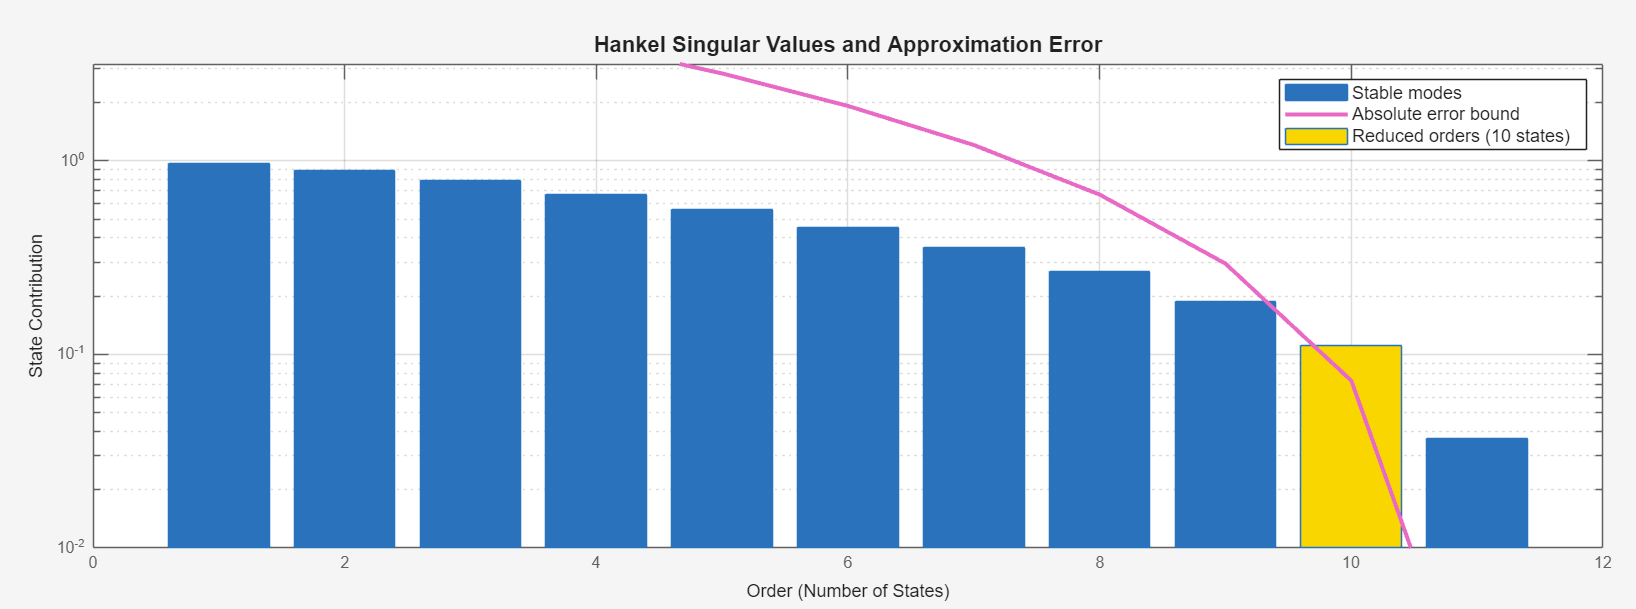

T=1

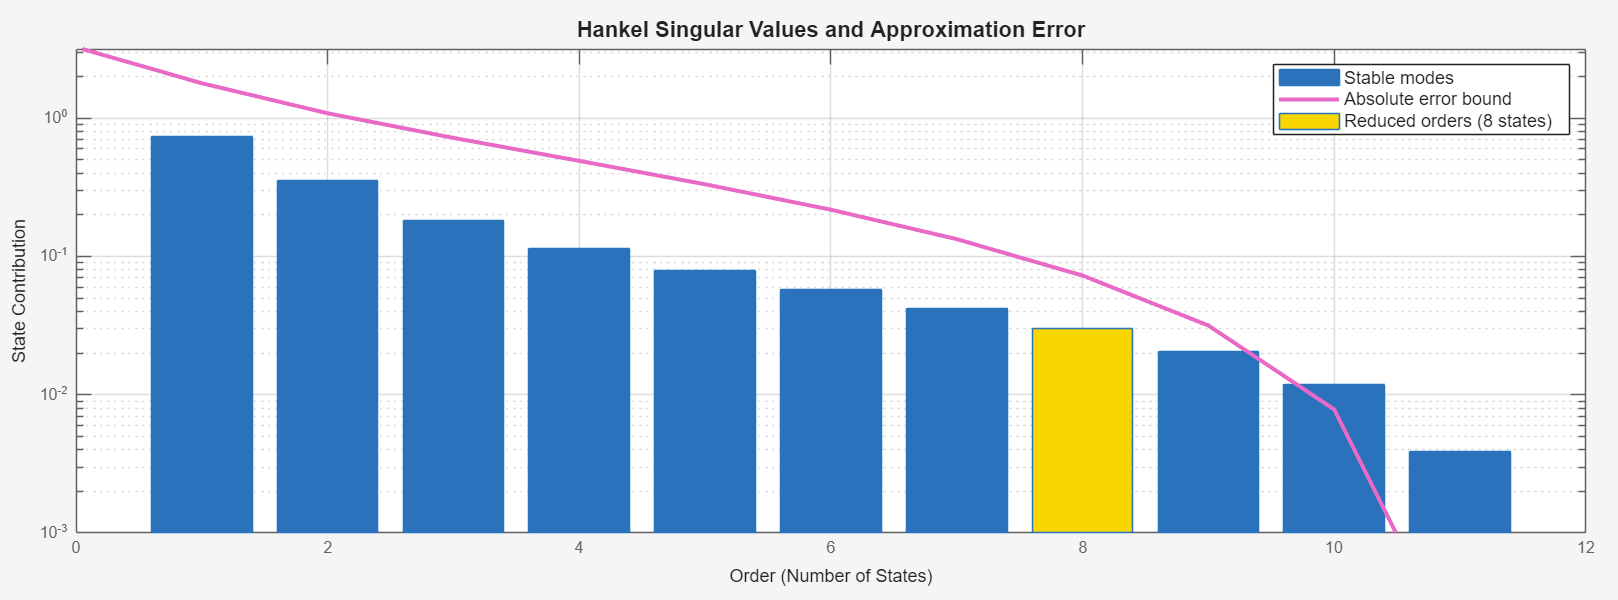

T=10